## With G(wj) given

Gwj = -0.5;

N = -1/Gwj;
M = pi;

x0 = 4*M/(pi*N) %Amplitude 


## Q9 stuff

%Char poly - s^2 + Kds + Kp => Kd = 1.5 for 0.75 damp
Kd = 1.5;
Kp = 1;
s = tf('s');
act = 1/(0.1*s + 1);
ILTF = feedback(act/s,Kd);
CLTF = feedback(ILTF*Kp/s,1);
damp(CLTF)
%w = 1.09


## Function stuff

sys = linmod('exam2021')

sys = struct with fields:
             a: [3×3 double]
             b: [3×1 double]
             c: [-10 -15 -10]
             d: 0
     StateName: {3×1 cell}
    OutputName: {'exam2021/Outport'}
     InputName: {'exam2021/Inport'}
     OperPoint: [1×1 struct]
            Ts: 0


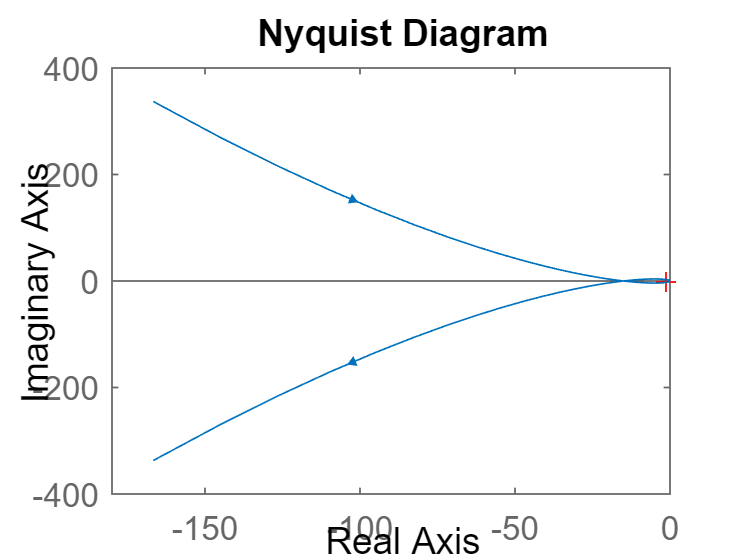

A = sys.a;
B = sys.b;
C = sys.c;
D = sys.d;
nyquist(-ss(A,B,C,D))

%run in command window to zoom
%w = 1, intersects at -15

N = -1/-15;
L = 0.5;

x0 = 4*L/(pi*N) %Amplitude 

x0 = 9.5493


sys = linmod('exam2021_anti')

sys = struct with fields:
             a: [4×4 double]
             b: [4×1 double]
             c: [-10 -15 -10 -10]
             d: 0
     StateName: {4×1 cell}
    OutputName: {'exam2021_anti/Outport'}
     InputName: {'exam2021_anti/Inport'}
     OperPoint: [1×1 struct]
            Ts: 0


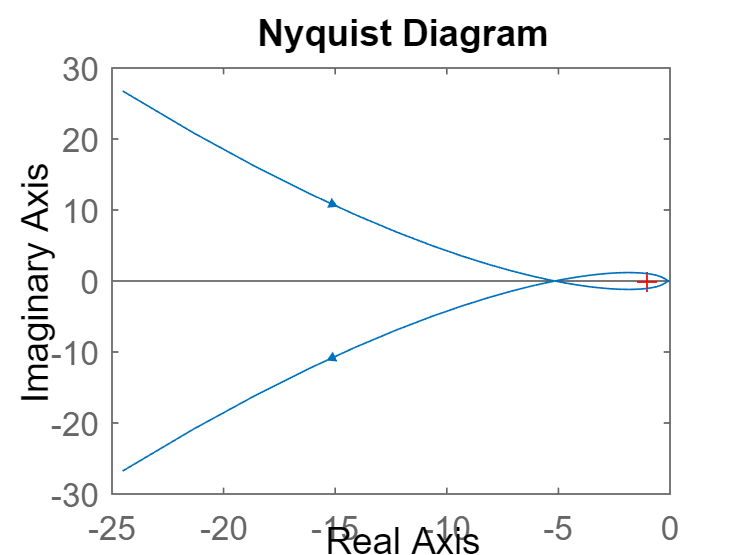

A = sys.a;
B = sys.b;
C = sys.c;
D = sys.d;
nyquist(-ss(A,B,C,D))

%w = .66, intersects at -5.2

N = -1/-5.2;
L = 0.5;

x0 = 4*L/(pi*N) %Amplitude 

x0 = 3.3104